# Experiments with Travelling Salesman Problem

This scipt runs the evolutionary algorithm from doTsp.m for different parameters. Each combination of one/two point crossover with random/neighbour mutation is run 100 times and the results are plotted.

clear;
cities = importdata('cities.csv');
nGenes = length(cities.data);

## Experiment 1

Mutation: Use random swapping of cities when mutating Recombination: Use one point crossover

p(1).maxGenerations = 30;
p(1).populationSize = 20;
p(1).crossoverRate = 0.9;
p(1).mutationRate = 1/nGenes;
p(1).nNiches = p(1).populationSize/4;
p(1).useNiching = false;
p(1).useRandomMutation = true;
p(1).useOnePointCrossover = true;
p(1).cities = cities;
name{1} = 'random one point';

## Experiment 2

Mutation: Swap neighboured cities only when mutating Recombination: Use one point crossover

p(2) = p(1);
p(2).useRandomMutation = false;
p(2).useOnePointCrossover = true;
name{2} = 'neighbour one point';

## Experiment 3

Mutation: Use random swapping of cities when mutating Recombination: Use two point crossover

p(3) = p(1);
p(3).useRandomMutation = true;
p(3).useOnePointCrossover = false;
name{3} = 'random two point';

## Experiment 4

Mutation: Swap neighboured cities only when mutating Recombination: Use two point crossover

p(4) = p(1);
p(4).useRandomMutation = false;
p(4).useOnePointCrossover = false;
name{4} = 'neighbour two point';

## Run Experiments

for i=1:4
    tic;
    clear bestFitness medianFitness;
    parfor run = 1:100
        r(run) = doTsp(p(i));
        bestFitness(run,:) = r(run).bestFitness;
        medianFitness(run,:) = r(run).medianFitness;
    end
    p(i).medianBestFitness = median(bestFitness,1);
    p(i).medianMedianFitness = median(medianFitness,1);
    toc;
end

Starting parallel pool (parpool) using the 'local' profile ... connected to 2 workers.


Elapsed time is 43.625080 seconds.
Elapsed time is 13.404031 seconds.
Elapsed time is 15.375552 seconds.
Elapsed time is 13.257284 seconds.


## Plot Fitnesses

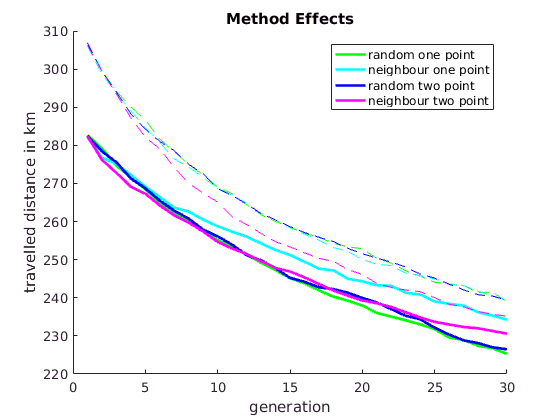

figure(1);clf;hold on;
% Helper Library for a better color distribution over plots
colorSet = varycolor(4);
for i=1:4
    lineHandles(i) = plot(-1*p(i).medianBestFitness,'-','LineWidth',2,'Color',colorSet(i,:));
    plot(-1*p(i).medianMedianFitness,'--','Color',get(lineHandles(i),'Color'));
end
ylabel('travelled distance in km');
xlabel('generation');
legend(lineHandles,name,'Location','NorthEast');
title('Method Effects');

## Conclusion

It can be seen that the random mutation outperforms the swapping of only neigbouring cities. Random mutation in combination with two point crossover works best, but in general two point crossover only slightly outperforms one point crossover.